## Part 1

Load and visualize ’Barbara’image using 3 different ways 1).mat file, 2) .png file with Image Processing Toolbox from Matlab, 3) .png file with Peter Corke toolbox in Matlab.

### 1)

% Load barbara as mat file
barbara_mat =  load(fullfile("./","barbara.mat")).barbara;

% display barbara as mat file
disp("barbara_mat");

barbara_mat


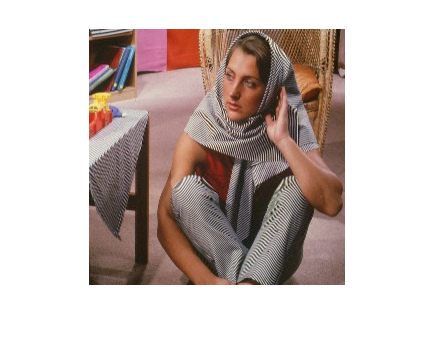

imshow(barbara_mat);

### 2)

% Load barbara as png with Image Processing Toolbox
barbara_imptb = imread('barbara.png');

% diplay barbara as png with Image Processing Toolbox
disp("barbara_imptb");

barbara_imptb


imshow(barbara_imptb);

### 3)

% Load barbara as png with Peter Corke toolbox
barbara_mvtb = iread('barbara.png');
% display barbara as png with Peter Corke toolbox
disp("barbara_mvtb");

barbara_mvtb


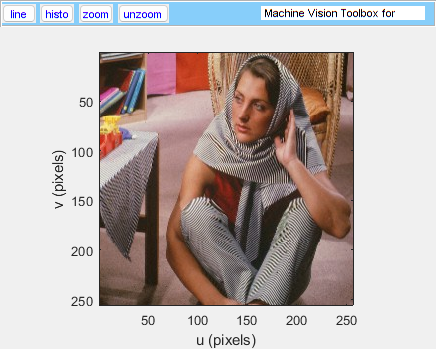

idisp(barbara_mvtb);

## Part 2

Convert to grayscale.

% Make greyscale image
barbara_grey = rgb2gray(barbara_mat);
% Display that image
disp("Grey barbara");

Grey barbara


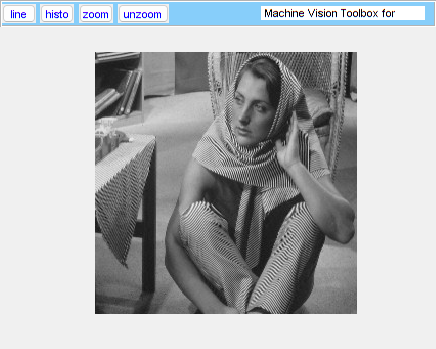

imshow(barbara_grey);

## Part 3

Check image size, number of channels, and convert between classes e.g. double to uint8 and vice versa


% Print out the shape of the images, last number is number of channels
% if last index does not exist it has 1 channel
disp("RGB barbara size has 3 channels thus size array is len(3) and index (3) is 3, i.e. nr of channels");

RGB barbara size has 3 channels thus size array is len(3) and index (3) is 3, i.e. nr of channels


size(barbara_mat)

ans =    256   256     3


disp("Grey barbara size has 1 channel, thus size array is len(2)");

Grey barbara size has 1 channel, thus size array is len(2)


size(barbara_grey)

ans =    256   256


## Part 4

Image scale down to half and quarter size

barbara_small = imresize(barbara_grey,0.5);
barbara_smaller = imresize(barbara_grey,0.25);

#### Half

size(barbara_small)

ans =    128   128


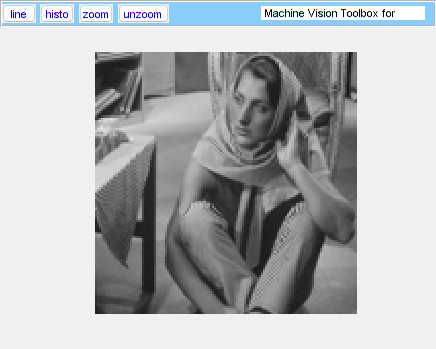

imshow(barbara_small)

#### Quarter

size(barbara_smaller)

ans =     64    64


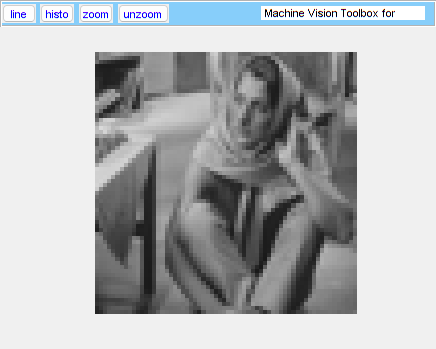

imshow(barbara_smaller)

## Part 5

Modify brightness and visualize their respective image histograms of the grayscale image in its original size

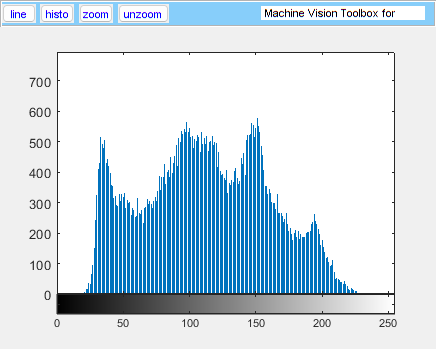


% We can do this by modifying gamma, but that does not produce
% the exact same image information
imhist(barbara_grey);

imshow(barbara_grey);

#### Make the image brigher

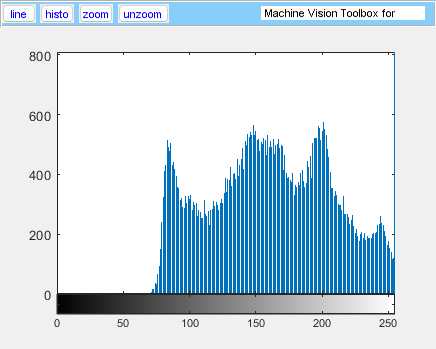

% make the image brighter
imhist(barbara_grey+50);

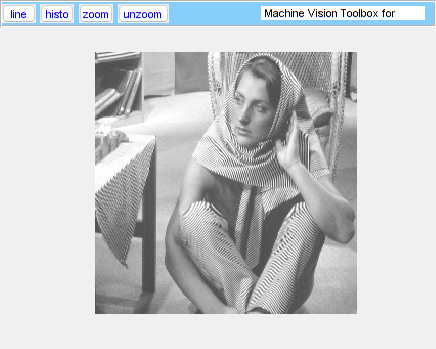

imshow(barbara_grey+50);

#### Make the image dimmer

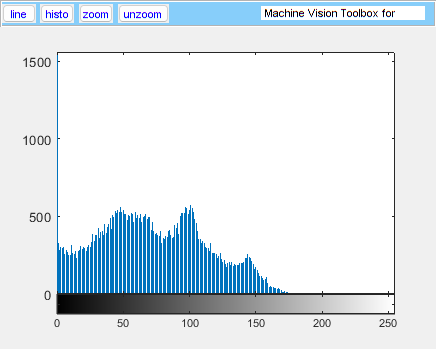

% make the image dimmer
imhist(barbara_grey-50);

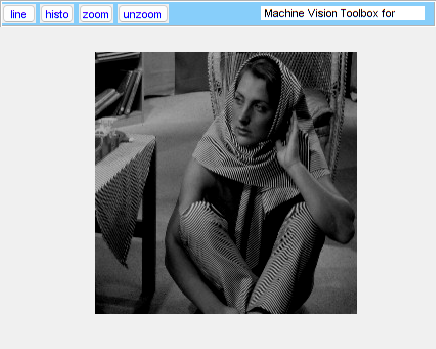

imshow(barbara_grey-50);

## Part 6

Investigate other functions in matlab related to filtering, binarization, edge detection (fspecial’, ’imfilter’, ’imerode’, ’imadjust’, ’imhist’, ’histeq’, ’edge’, ’im2bw’,..)

### Smooth the image with averaging kernel

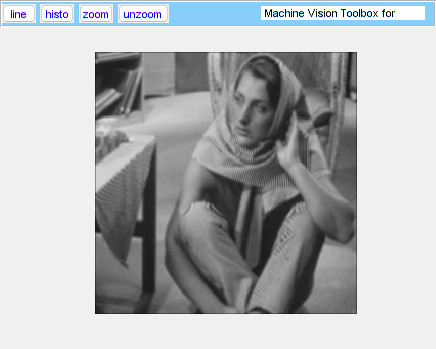

kernel = fspecial('average',3);
imshow(imfilter(barbara_grey,kernel))

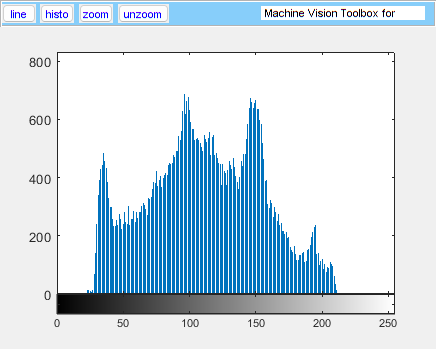

imhist(imfilter(barbara_grey,kernel))

### Smooth with a gaussian blur

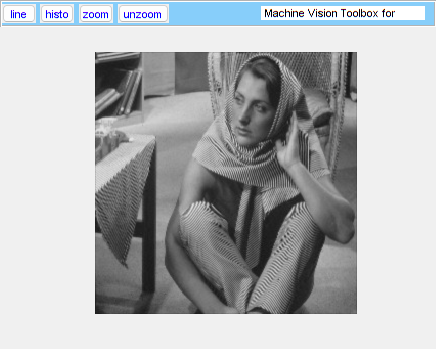

kernel = fspecial('gaussian',3,.5);
imshow(imfilter(barbara_grey,kernel))

### Erode the image with a diamond structure

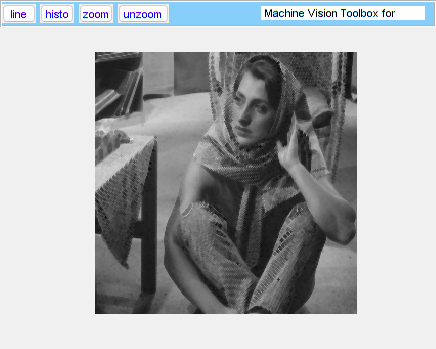

se = strel('diamond',1);
imshow(imerode(barbara_grey,se));

### Imadjust

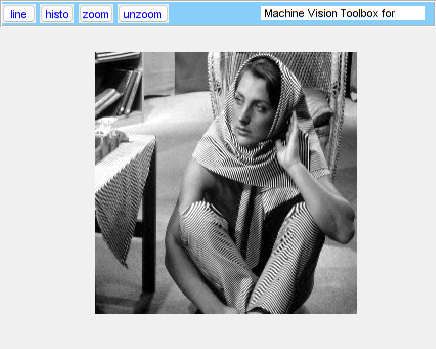

imshow(imadjust(barbara_grey))

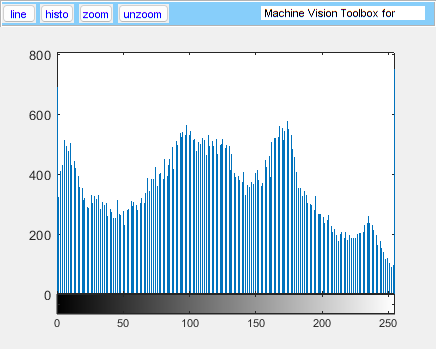

imhist(imadjust(barbara_grey))

### Hist equalization

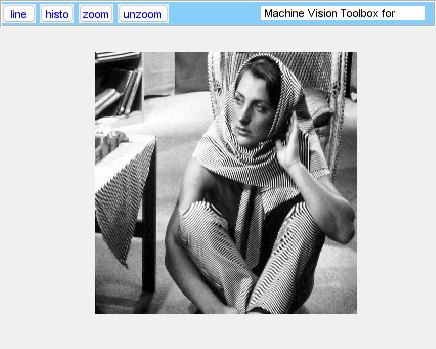

imshow(histeq(barbara_grey))

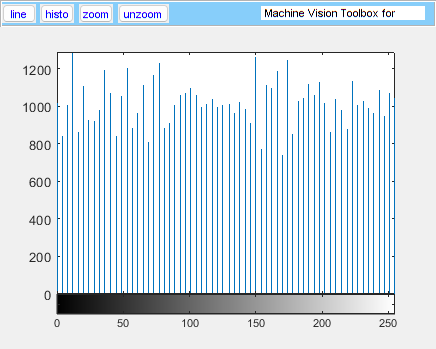

imhist(histeq(barbara_grey))

### Edge detection

with the canny detector

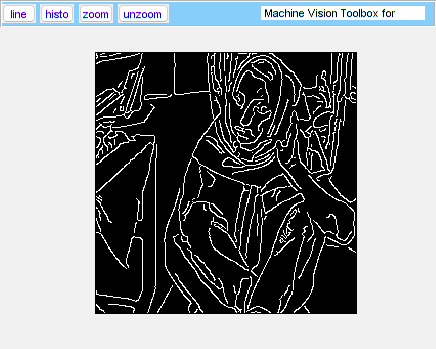

imshow(edge(barbara_grey,"canny"))

with the LoG detector

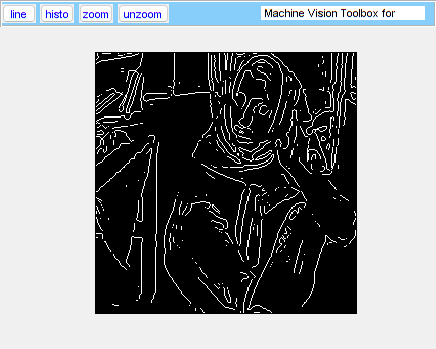

imshow(edge(barbara_grey,"log"))

with the sobel detector

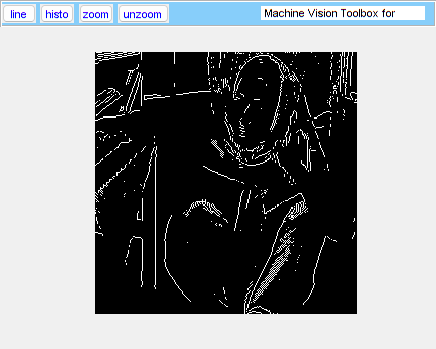

imshow(edge(barbara_grey,"sobel"))

It's apperant that the canny edge detector performes the best, second is the Laplacian of gaussian edge detector, and third is the sobel edge detector which seems to perfomes better on smaller edges such as the ones on the pants